# Test Mappings

clear vars; close all; clc;
warning('off','all')

% Number of observables
numObs = 15;
% Define dimension of modes
SSMDim = 6; hSSMDim = SSMDim/2;
load obsDecayDataC

## Visualize Training Data

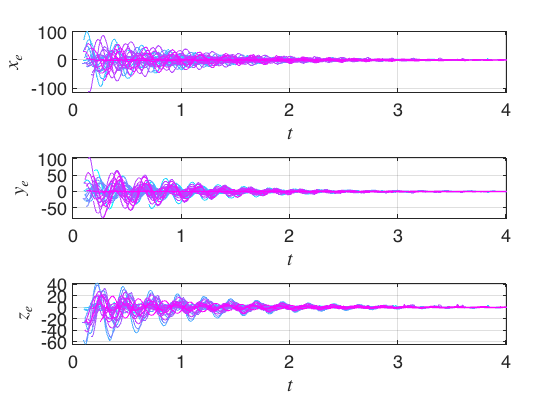

trajs = [13, 14, 15];
numCoord = length(trajs);
customFigure('subPlot',[numCoord 1]);
labels = ["$x_a$", "$y_a$", "$z_a$", ...
    "$x_b$", "$y_b$", "$z_b$", ...
    "$x_c$", "$y_c$", "$z_c$", ...
    "$x_d$", "$y_d$", "$z_d$", ...
    "$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:numCoord
    subplot(numCoord,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(trajs(iPlt)),'Interpreter','latex');
end

for iTraj = 1:size(oData, 1)
    for iObs = 1:numCoord
        subplot(numCoord,1,iObs);
        plot(oData{iTraj,1},oData{iTraj,2}(trajs(iObs),:),'Linewidth',1)
    end
end

Consider only the tip positions, neglect other sensor data in this script.

tipData = oData;
for iTraj = 1:size(oData, 1)
    tipData{iTraj,2} = oData{iTraj,2}(trajs,:);
end

Perform delay-embedding. As observables for the model, we consider the current tip position data as well as past measurements (no future ones) of the tip position data. For this case (we only consider the tip), we have a minimum of `4` delays, which is augmented by the `overEmbed` variable, so that the number of total delays is `4+overEmbed`. We also do some cutting, but it is not necessary in this current case.

overEmbed = 21;
[yData, opts_embd] = coordinatesEmbeddingControl(tipData, SSMDim, 'OverEmbedding', overEmbed);

The 78 embedding coordinates consist of the 3 measured states and their 25 time-delayed measurements.


embedDim = size(yData{1,2},1);
outdofs = [embedDim-2 embedDim-1 embedDim];
sliceInt = [0.01, Inf];
yDataTrunc = sliceTrajectories(yData, sliceInt);

PCA is still useful in the delay-embeeded space, as the number of modes explaining most of the data should be the dimension of the SSM. Indeed, we get it as more than 90% of variance is explained by the first six PCA modes.

disp('PCA')

PCA


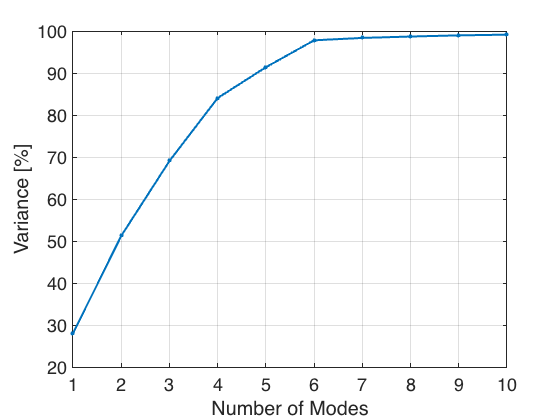

Xsnapshots = cat(2,yDataTrunc{:,2});
% Perform SVD on displacement field
[V,S,~] = svd(Xsnapshots, 0);
% Note we assume data centered around the origin, which is the
% fixed point of our system
customFigure;
maxModesPlot = 10;
l2vals = diag(S).^2;
plot(1:length(l2vals),cumsum(l2vals)/sum(l2vals)*100,'.-','Linewidth',2,'MarkerSize',12)
xlabel('Number of Modes');
ylabel('Variance [%]');
xlim([1 maxModesPlot])
set(gca,'XTick',[1:1:maxModesPlot])


Vde = V(:,1:SSMDim);
% Set reduced-coordinates as PCA projection to the first six modes
etaDataTrunc = yDataTrunc;
for iTraj = 1:size(oData, 1)
    etaDataTrunc{iTraj,2} = transpose(Vde)*yDataTrunc{iTraj,2};
end
% Define modes
SSMDim = 6; hSSMDim = SSMDim/2;

% Set test and train trajectories
indTest = [5 15 21 32 38];
indTrain = setdiff(1:size(oData, 1),indTest);

## Geometry

Manifold fitting with prescribed graph. Higher orders tend to overfit.

SSMOrder = 1;
if SSMOrder == 1
    % Need to recompute as the columns of Vde might change in order
    IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder);
    Vde = IMInfo.parametrization.tangentSpaceAtOrigin;
    etaDataTrunc = yDataTrunc;
    for iTraj = 1:size(oData, 1)
        etaDataTrunc{iTraj,2} = transpose(Vde)*yDataTrunc{iTraj,2};
    end
else
    IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder,'reducedCoordinates',etaDataTrunc(indTrain,:));
    IMInfo.chart.map = @(x) transpose(Vde)*x;
end

Evaluate learning of geometry.

%% Trajectory lifting requires reduced coordinates (ensures y is on manifold, 
% hence yRec =/= yDataTrunc)
disp('Results of geometry fit:')

Results of geometry fit:


yRec = liftTrajectories(IMInfo, etaDataTrunc);
normedTrajDist = computeTrajectoryErrors(yRec, yDataTrunc);
meanErrorGeoTrain = mean(normedTrajDist(indTrain))*100

meanErrorGeoTrain = 4.6888

meanErrorGeoTest = mean(normedTrajDist(indTest))*100

meanErrorGeoTest = 4.0393

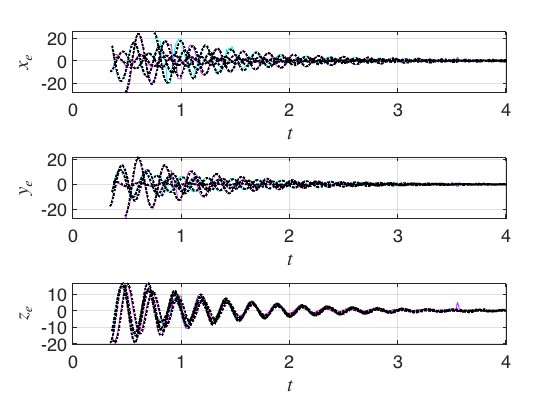


% Plot test data
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
    end
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yRec{indTest(iTraj),1},yRec{indTest(iTraj),2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end

## Reduced dynamics

Cubic order dynamics halves the trajectory error of linear dynamics. The `Map` case seems more accurate than the `Flow` one.

ROMOrder = 3;
RDInfo = IMDynamicsFlow(etaDataTrunc(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'default');

Estimation of the reduced dynamics...  Done. 


RDInfo.eigenvaluesLinPartFlow(1:3)

ans =   -1.0378 +26.3800i
  -1.1831 +26.3859i
  -1.2052 +26.9423i


Rauton = RDInfo.reducedDynamics.map

Rauton = function_handle with value:
    @(x)W_r*phi(x)

Evaluate learning of reduced dynamics.

disp('Errors for the dynamics on reduced-coordinates:')

Errors for the dynamics on reduced-coordinates:


etaRec = advectRD(RDInfo, etaDataTrunc);
normedTrajDist = computeTrajectoryErrors(etaRec, etaDataTrunc);
meanErrorDynTrain = mean(normedTrajDist(indTrain))*100

meanErrorDynTrain = 8.6850

meanErrorDynTest = mean(normedTrajDist(indTest))*100

meanErrorDynTest = 9.2367

## Check mapping from observables to observables (with inputs)

$v:\Re^n \to \Re^p$ is the mapping from $\mathit{\mathbf{y}}$ to $\bar{\mathit{\mathbf{x}}}$ 

$w:\Re^p \to \Re^n$ is the mapping from $\bar{\mathit{\mathbf{x}}}$ to $\mathit{\mathbf{y}}$ 

load koopman_data_figureEight

% Testing mapping function
zu{1, 1} = t; zu{1, 2} = y - y(:, end);
[yDataInput, Yu_opts_embd] = coordinatesEmbeddingControl(zu, SSMDim, 'OverEmbedding', overEmbed);

The 78 embedding coordinates consist of the 3 measured states and their 25 time-delayed measurements.



% v mapping
yDataRemapped = yDataInput;
xData = yDataInput;
for iTraj = 1:size(yDataInput, 1)
    xData{iTraj, 2} = transpose(Vde) * yDataInput{iTraj, 2};
    yDataRemapped{iTraj, 2} = Vde * xData{iTraj, 2};
end

% w mapping

Plot $\mathit{\mathbf{y}}=\left(w\circ v\right)\left(\mathit{\mathbf{y}}\right)$. Expect similar results

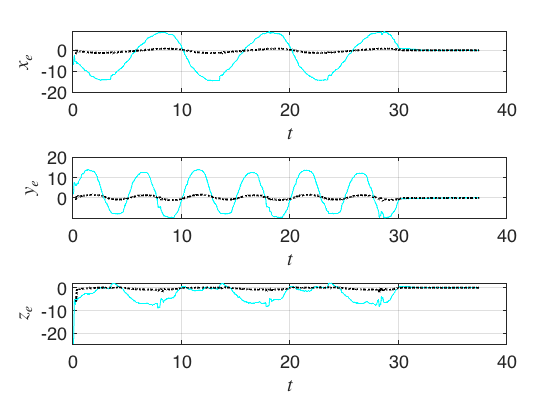

customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
% Plotting true position of tip
for iTraj = 1:length(size(yDataRemapped, 1))
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(zu{iTraj,1},zu{iTraj,2}(iObs,:),'Linewidth',1)
    end
end

% Plotting estimated position of tip on SSM
for iTraj = 1:length(size(yDataRemapped, 1))
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yDataRemapped{iTraj,1},yDataRemapped{iTraj,2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end

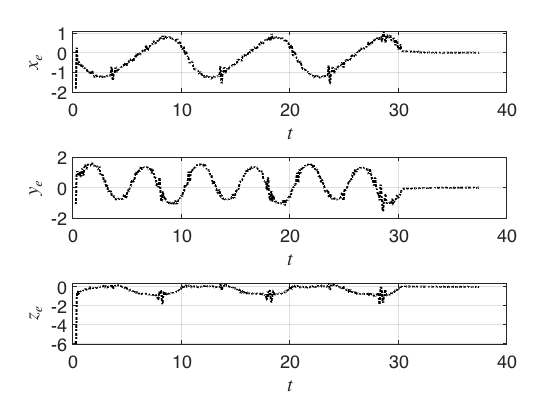


% Plot SSM-approximated tip position by itself to see shape
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iTraj = 1:length(size(yDataRemapped, 1))
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yDataRemapped{iTraj,1},yDataRemapped{iTraj,2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end


normedTrajDataDist = computeTrajectoryErrors(yDataRemapped, yDataInput);
meanErrorGeoData = mean(normedTrajDataDist)*100

meanErrorGeoData = 54.3876

## Learn control matrix

% load koopman_data
% Consolidate data into standard var names and shift observation to origin
% z = y - y(:, end); U = u;
% zu = cell(1, 3); 
% zu{1, 1} = t; zu{1, 2} = z; 
% zu{1, 3} = u;

load koopman_data_figureEight
zu{1, 1} = t; zu{1, 2} = y - y(:, end);
% zu{2,1} = t; zu{2,2} = y - y_eq'; zu{2,3} = u;

% Project observables then lift (if required)
[Yu, yu_opts_embd] = coordinatesEmbeddingControl(zu, SSMDim, 'OverEmbedding', overEmbed);

The 78 embedding coordinates consist of the 3 measured states and their 25 time-delayed measurements.




tTrain = Yu{1, 1} - Yu{1, 1}(1);
UTrain = zu{1,3}(:, idxStart:end);
% Project lifted observation down to tangent space
xBarData = transpose(Vde) * Yu{1,2};

% TODO: Debugging (Magnitudes are waaaay off)
etaData = {}; etaData{1,1} = tTrain; etaData{1,2} = xBarData;

yIMData = { tTrain, Vde * etaData{1,2} };
zIMData = yIMData{1,2}(outdofs(1):outdofs(3),:);

% customFigure('subPlot',[numCoord 1]);
% subplot(numCoord,1,1);
% for iPlt = 1:length(outdofs)
%     subplot(numCoord,1,iPlt);
%     xlabel('$t$','Interpreter','latex');
%     ylabel(labels(iPlt),'Interpreter','latex');
% end
% for iTraj = 1:length(size(yDataRemapped, 1))
%     for iObs = 1:length(outdofs)
%         subplot(numCoord,1,iObs);
%         plot(yIMData{iTraj,1},yIMData{iTraj,2}(outdofs(iObs),:),'k:','Linewidth',2)
%     end
% end
% 
% 
% % Compute finite difference for data and truncate U to match dimensions
% apprxOrd = 3;
% [dXBarDt,xBarData,tTrain] = finiteTimeDifference(xBarData, tTrain, apprxOrd); % Truncates X_bar 3 places on each side
% UTrain = UTrain(:, 1+apprxOrd:end-apprxOrd);
% 
% dXbarDt_aut = Rauton(xBarData); % Evaluate autonomous ROM dynamics for each Xbar
% 
% % Set options for ridgeRegression
% varargin = {'R_PolyOrd', [3], 'style', 'default'};
% L2 = 1 + 0 * exp(0*tTrain);
% 
% % Learn whole B matrix
% [B_learn,l_opt,Err] = ridgeRegression(UTrain, dXBarDt - dXbarDt_aut, L2, [], 0);
% R = @(t,x,u) Rauton(x) + B_learn*u;

**Validate Control model**

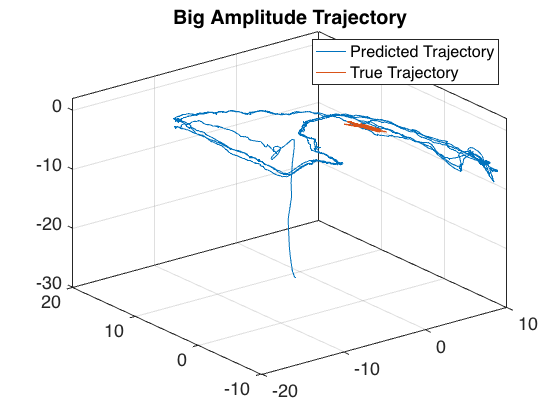

load koopman_data_figureEight
% load koopman_data
zTrue = y - y_eq';
tTrue = t;
uTrue = u'; % First dimension of interpolated value must be same size as t
uFun = @(t) transpose(interp1(tTrue, uTrue, t));
[tTraj,xTraj] = ode45(@(t,x) R(t,x,uFun(t)),tTrue,zeros(SSMDim,1)); % Assume we start at origin

xRecData = cell(1, 2); xRecData{1,1} = tTraj; xRecData{1,2} = xTraj';
yVal = Vde * xRecData{1,2};
zVal = yVal(outdofs(1):outdofs(3),:);

% Visualize the trajectory
customFigure; 
plot3(zTrue(1, :), zTrue(2, :), zTrue(3, :));
plot3(zVal(1, :), zVal(2, :), zVal(3, :));
legend('Predicted Trajectory', 'True Trajectory');
title('Big Amplitude Trajectory');
view(3);